clear()

syms t f_1 f_2 t_1 t_2 real
assume(t_1 < t_2)
assume(t >= t_1)
assume(t <= t_2)
assume(f_1 >= 0)
assume(f_2 >= 0)

linFMSymFcn = f_1 + (f_2 - f_1) / (t_2 - t_1) * (t - t_1)

$$linFMSymFcn = f_{1}+\frac{\left(f_{1}-f_{2}\right)\,\left(t-t_{1}\right)}{t_{1}-t_{2}}$$

logFMSymFcn = f_1 * exp((log(f_2) - log(f_1)) / (t_2 - t_1) * (t - t_1))

$$logFMSymFcn = f_{1}\,{\mathrm{e}}^{\frac{\left(\log\left(f_{1}\right)-\log\left(f_{2}\right)\right)\,\left(t-t_{1}\right)}{t_{1}-t_{2}}}$$

testT = linspace(t1, t2, 10000)

testT =          0    0.0001    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0016    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0027    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049


t1 = 0

t1 = 0

t2 = 1

t2 = 1

f1 = 0.0001

f1 = 1.0000e-04

f2 = 5

f2 = 5


subArgs = {[t_1, t_2, f_1, f_2], [t1, t2, f1, f2]}

subArgs = 1×2 cell array
    {[t_1    t_2    f_1    f_2]}    {[0 1 1.0000e-04 5]}


sym2func = @(sym) matlabFunction(subs(sym, subArgs{:}))

sym2func = function_handle with value:
    @(sym)matlabFunction(subs(sym,subArgs{:}))



linRampFcn = sym2func(linFMSymFcn)

linRampFcn = function_handle with value:
    @(t)t.*4.9999+1.0e-4


logRampFcn = sym2func(logFMSymFcn)

logRampFcn = function_handle with value:
    @(t)exp(t.*(log(5.0)+log(1.0e+4)))./1.0e+4


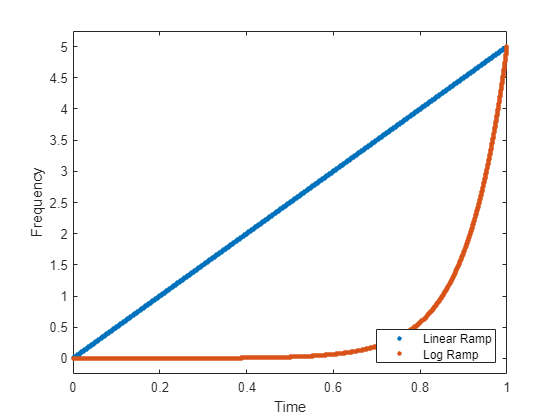

figure()
plot(testT, linRampFcn(testT), ...
    '.', DisplayName='Linear Ramp', MarkerSize=10);
hold on
plot(testT, logRampFcn(testT), ...
    '.', DisplayName='Log Ramp', MarkerSize=10);
xlabel('Time');
ylabel('Frequency');
ylim([f1, f2] + ([-1, 1] * (f2 - f1) * 0.05));
legend(Location='southeast');

linFMPhaseSymFcn = 2 * pi * int(linFMSymFcn, t);
linFMPhaseSymFcn = linFMPhaseSymFcn - subs(linFMPhaseSymFcn, t, t1)

$$linFMPhaseSymFcn = 2\,\pi \,\left(f_{1}\,t+\frac{\left(f_{1}-f_{2}\right)\,{\left(t-t_{1}\right)}^{2}}{2\,\left(t_{1}-t_{2}\right)}\right)-\frac{\pi \,{t_{1}}^{2}\,\left(f_{1}-f_{2}\right)}{t_{1}-t_{2}}$$

logFMPhaseSymFcnUnadj = 2 * pi * int(logFMSymFcn, t)

$$logFMPhaseSymFcnUnadj = \frac{2\,\pi \,f_{1}\,{\left(\frac{f_{1}}{f_{2}}\right)}^{\frac{t-t_{1}}{t_{1}-t_{2}}}\,\left(t_{1}-t_{2}\right)}{\log\left(\frac{f_{1}}{f_{2}}\right)}$$

logFMPhaseSymFcn = logFMPhaseSymFcnUnadj - subs(logFMPhaseSymFcnUnadj, t, t1)

$$logFMPhaseSymFcn = \frac{2\,\pi \,f_{1}\,{\left(\frac{f_{1}}{f_{2}}\right)}^{\frac{t-t_{1}}{t_{1}-t_{2}}}\,\left(t_{1}-t_{2}\right)}{\log\left(\frac{f_{1}}{f_{2}}\right)}-\frac{2\,\pi \,f_{1}\,\left(t_{1}-t_{2}\right)}{\log\left(\frac{f_{1}}{f_{2}}\right)\,{\left(\frac{f_{1}}{f_{2}}\right)}^{\frac{t_{1}}{t_{1}-t_{2}}}}$$

linRampPhaseFcn = sym2func(linFMPhaseSymFcn)

linRampPhaseFcn = function_handle with value:
    @(t)pi.*(t./1.0e+4+t.^2.*2.49995).*2.0


logRampPhaseFcn = sym2func(logFMPhaseSymFcn)

logRampPhaseFcn = function_handle with value:
    @(t)(pi.*(-2.0e-4))./log(5.0e+4)+(2.0e-5.^(-t).*pi)./(log(5.0e+4).*5.0e+3)


logMatlabFunc = matlabFunction(logFMPhaseSymFcnUnadj, 'Vars', [t, t_1, t_2, f_1, f_2])

logMatlabFunc = function_handle with value:
    @(t,t_1,t_2,f_1,f_2)(f_1.*pi.*(f_1./f_2).^((t-t_1)./(t_1-t_2)).*(t_1-t_2).*2.0)./log(f_1./f_2)


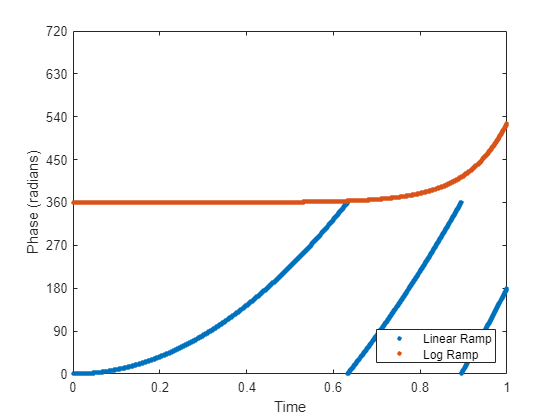

figure()
plot(testT, rad2deg(wrapTo2Pi(linRampPhaseFcn(testT))), ...
    '.', DisplayName='Linear Ramp', MarkerSize=10);
hold on
plot(testT, rad2deg(wrapTo2Pi(logRampPhaseFcn(testT))) + 360, ...
    '.', DisplayName='Log Ramp', MarkerSize=10);
xlabel('Time');
ylabel('Phase (radians)');
ylim([0, 360 * 2]);
yticks(0:90:(360 * 2));
legend(Location='southeast');

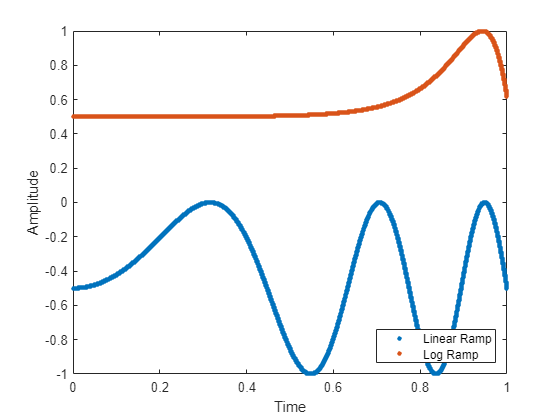

figure()
plot(testT, sin(wrapTo2Pi(linRampPhaseFcn(testT)))/2 - 0.5, ...
    '.', DisplayName='Linear Ramp', MarkerSize=10);
hold on
plot(testT, sin(wrapTo2Pi(logRampPhaseFcn(testT)))/2 + 0.5, ...
    '.', DisplayName='Log Ramp', MarkerSize=10);
xlabel('Time');
ylabel('Amplitude');
legend(Location='southeast');